# Higher-Order Taylor Methods

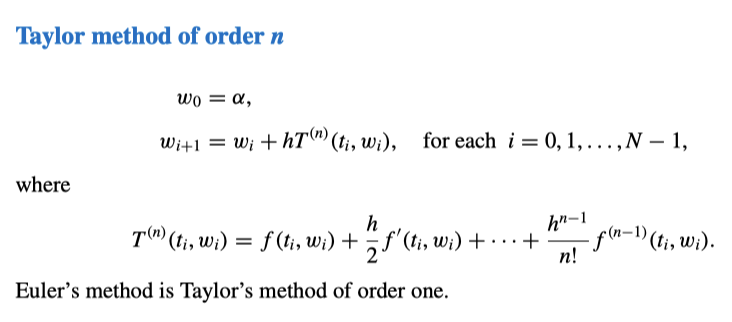

## Initialization

clc; clear; close all; %initialization

## Input the data

a=0; %input the left endpoint
b=2; %input the right endpoint
ya=0.5; %input the initial value on y(a)
N=10; %input the number of space
f=@(t,y) y-t^2+1;           %f
fd1=@(t,y) y-t^2+1-2*t;     %f'



## Computation

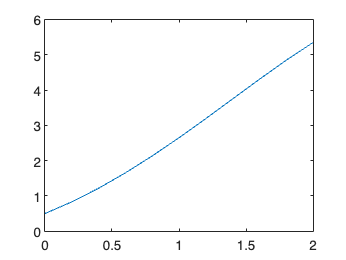

h=(b-a)/N;
t=[];
w=[];



t(0 +1)=a;
w(0 +1)=ya;
for i=1:1:N
    T=f(t(i-1 +1),w(i-1 +1))+h/2*fd1(t(i-1 +1),w(i-1 +1));
    w(i +1)=w(i-1 +1)+h*T;
    t(i +1)=a+i*h;
end
plot(t,w);

disp(w(end));

    5.3477

